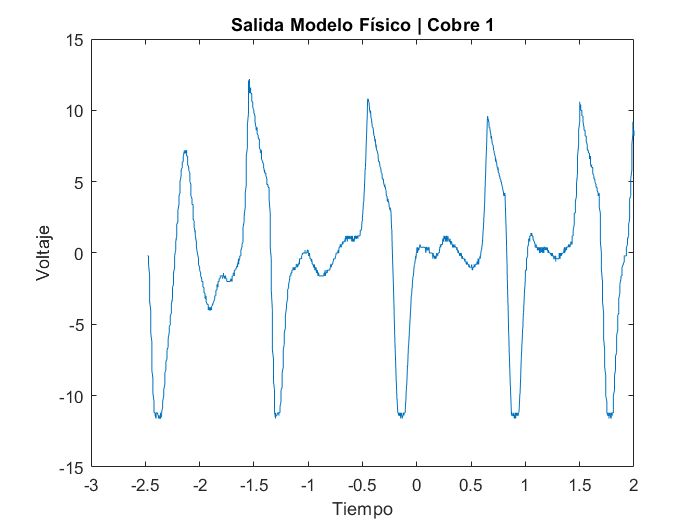

%Ruta del archivo
ruta_ampli11 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos cobre\Onda11.csv';

%Guardamos los datos
datos_ampli11 = csvread(ruta_ampli11);

%Extraemos las columnas
base_tiempos11 = datos_ampli11(:, 1);
voltaje11 = datos_ampli11(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje11_filt = filtfilt(filtro, voltaje11);

%Representamos los datos guardados
plot(base_tiempos11, voltaje11);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
title('Salida Modelo Físico | Cobre 1');

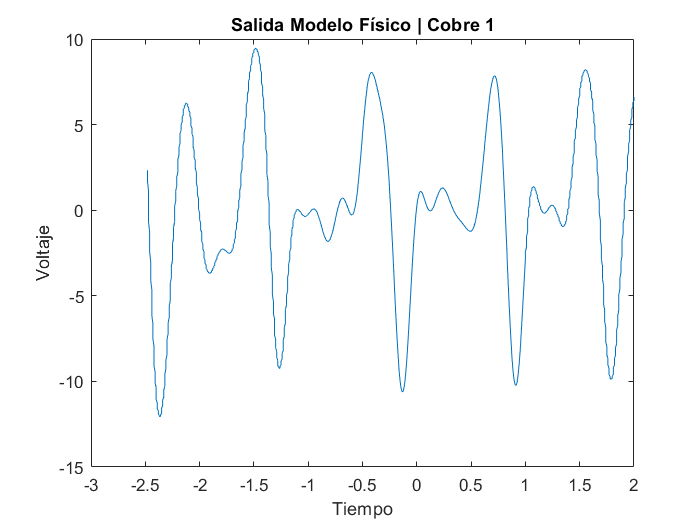


%Representamos los datos filtrados
plot(base_tiempos11, voltaje11_filt);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
title('Salida Modelo Físico | Cobre 1');

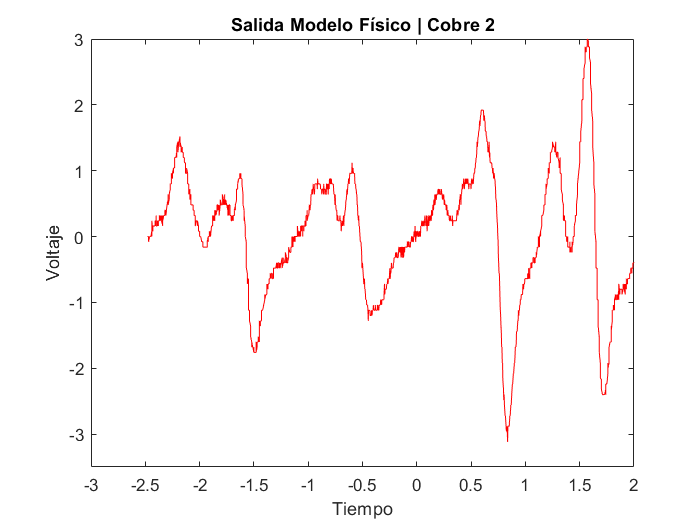

%Ruta del archivo
ruta_ampli12 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos cobre\Onda12.csv';

%Guardamos los datos
datos_ampli12 = csvread(ruta_ampli12);

%Extraemos las columnas
base_tiempos12 = datos_ampli12(:, 1);
voltaje12 = datos_ampli12(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje12_filt = filtfilt(filtro, voltaje12);

%Representamos los datos guardados
plot(base_tiempos12, voltaje12, 'Color', 'red');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
ylim([-3.5 3]);
title('Salida Modelo Físico | Cobre 2');

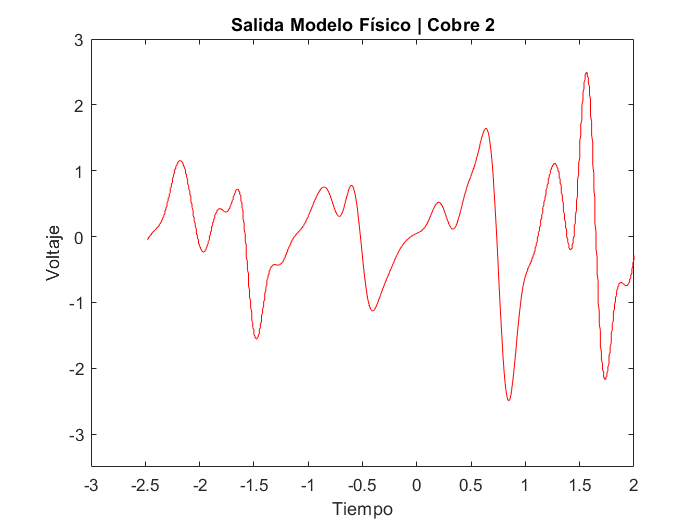


%Representamos los datos filtrados
plot(base_tiempos12, voltaje12_filt, 'Color', 'red');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
ylim([-3.5 3]);
title('Salida Modelo Físico | Cobre 2');

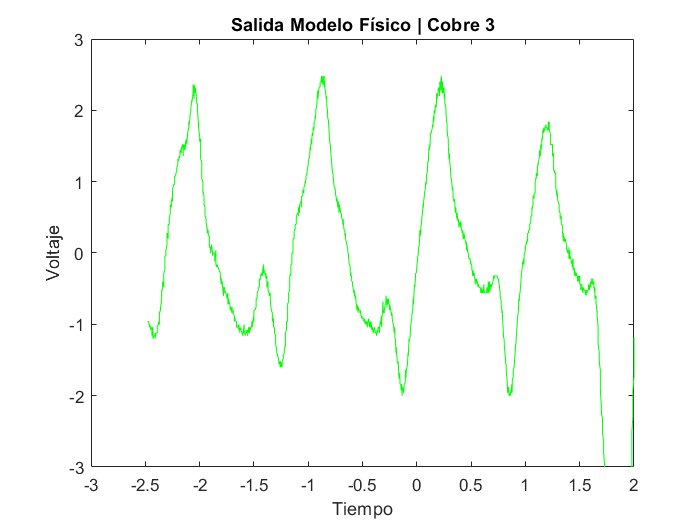

%Ruta del archivo
ruta_ampli13 = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\Datos_LAB\Electrodos cobre\Onda13.csv';

%Guardamos los datos
datos_ampli13 = csvread(ruta_ampli13);

%Extraemos las columnas
base_tiempos13 = datos_ampli13(:, 1);
voltaje13 = datos_ampli13(:, 2);

%Filtramos la señal
fs = 300;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje13_filt = filtfilt(filtro, voltaje13);

%Representamos los datos guardados
plot(base_tiempos13, voltaje13, 'Color', 'green');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
ylim([-3 3]);
title('Salida Modelo Físico | Cobre 3');

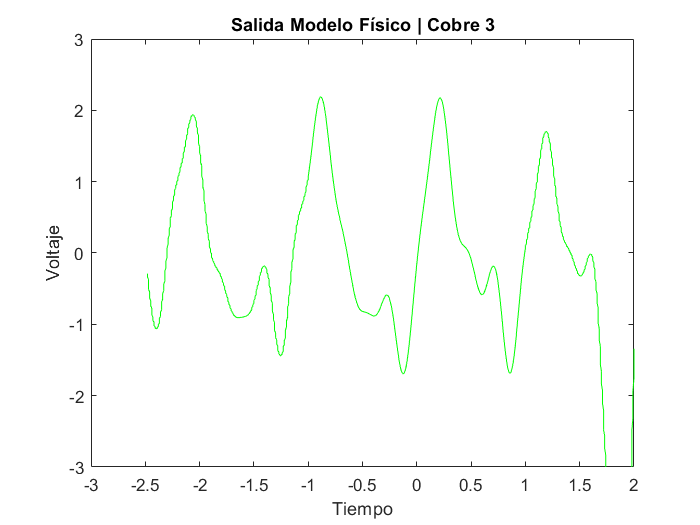


%Representamos los datos guardados
plot(base_tiempos13, voltaje13_filt, 'Color', 'green');
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-3 2]);
ylim([-3 3]);
title('Salida Modelo Físico | Cobre 3');